# Exam 2 Directory - [Move]

## Ch5 - Bracketing Roots

help bisect

 bisect: root location zeros
  [root,relErr,iter] = bisect(func,xl,xu,es,maxit,p1,p2,...)
  input:
    func = function handle (@)
    xl, xu = lower and upper guesses
    es = desired relative error (default = 0.0001%) (input %)
    maxit = maximum allowable iterations (default 50)
    p1,p2... = additional parameters used by func
  output:
    root = real root
    relErr = approximate relative error (%)
    iter = number of iterations



help falsepos

  falsepos: root location zeroes
  [root,froot,ea,iter]=falsepos(func,xl,xu,es,maxit,p1,p2,...):
  uses false position to find the root of func
  input:
    func = name of function
    xl, xu = lower and upper guesses
    es = desired relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by function
  output:
    root = root estimate
    froot = function at root estimate
    ea = approximate relative error (%)
    iter = number of iterations



help incsearch

  incsearch: incremental search root locator
  xb = incsearch(func,xmin,xmax,ns):
  finds brackets of x that contain sign changes
     of a function on an interval. Just moves left -> right, slow
  input:
    func = name of function
    xmin, xmax = endpoints of interval
    ns = number of subintervals (default = 50)
  output:
    xb(k,1) is the lower bound of the kth sign change
    xb(k,2) is the upper bound of the kth sign change
  If no brackets found, xb = [].



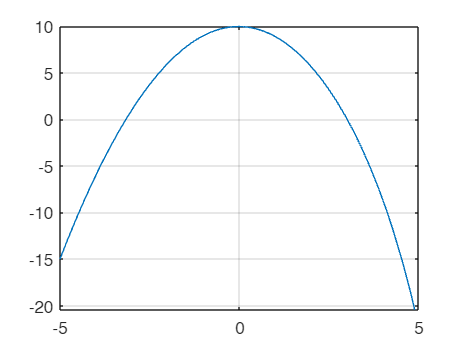


% Write inline function & check w/ plotting
func = @(x) -x.^2 - 1/20*exp(x)+10;
fplot(func,[-5 5]);
hold off; grid on;


% Bisection Method
%   Splits in half over and over. Keeps sign change interval
xl = 0; xu = 5; 
[root,relErr,iter] = bisect(func,xl,xu)

root = 2.9994

relErr = 7.9489e-05

iter = 21


% False Position
%   Two points, line through, find intersect, use next
%   Can be hurt by shape, best if close to linear
[root_FP,froot,ea,iter]=falsepos(func,xl,xu)

root_FP = 2.9994

froot = 4.8513e-06

ea = 3.8469e-05

iter = 16


% Incremental search method
%   Splits into evenly spaced chunks. Trouble if too wide.
%   Should hit all the roots
xb = incsearch(func,xl,xu,1000) % shows what brackets the sign change

number of root brackets:
     1



xb =     2.9980    3.0030


## Ch6 - Open Methods

help fixpt

  fixpt: fixed point iteration root locator
  [x1,ea,iter] = fixpt(g,x0,es,maxit)
  This function determines the root of x = g(x) with fixed
  The method is repeated until either the percent relative
  is equal to or less than es (default:1.e–6) or the number
  exceeds maxit (default:50).
  Input:
    g = the function for g(x)
    x0 = initial guess for x
    es = relative error stopping criterion (%)
    maxit = maximum number of iterations
  Output:
    x1 = solution estimate
    ea = relative error
    iter = number of iterations
 {



help newtraph

  newtraph: Newton-Raphson root location zeroes
  [root,ea,iter]=newtraph(func,dfunc,xr,es,maxit,p1,p2,...):
  uses Newton-Raphson method to find the root of func
  input:
    func = name of function
    dfunc = name of derivative of function
    xr = initial guess
    es = desired relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by function
  output:
    root = real root
    ea = approximate relative error (%)
    iter = number of iterations



help secant

 xr=secant(f,x1,x2,tol,maxIt)
 
 Implements the Secant Method
 
    f = function to find the root of
    x1 = first x value
    x2 = second x value
    tol = stopping criteria tolerance
    maxIt = maximum number of iterations
    xr = found root
 
 ABH
 Spring 2023



help modSecant

 xr=modSecant(f,x,delta,tol,maxIt)
 
 Implements the modified secant method
 
  f = function to find the root of
  x0 = initial value
  delta = value of delta
  tol = stopping criteria tolerance
  maxIt = maximum number of iterations
  xr = found root
 
 ABH
 Spring 2023



help roots

 roots  Find polynomial roots.
    roots(C) computes the roots of the polynomial whose coefficients
    are the elements of the vector C. If C has N+1 components,
    the polynomial is C(1)*X^N + ... + C(N)*X + C(N+1).
 
    Note:  Leading zeros in C are discarded first.  Then, leading relative
    zeros are removed as well.  That is, if division by the leading
    coefficient results in overflow, all coefficients up to the first
    coefficient where overflow occurred are also discarded.  This process is
    repeated until the leading coefficient is not a relative zero.
 
    Class support for input c: 
       float: double, single
 
    See also poly, residue, fzero.

    Documentation for roots
    

help polyval

 polyval Evaluate polynomial.
    Y = polyval(P,X) returns the value of a polynomial P evaluated at X. P
    is a vector of length N+1 whose elements are the coefficients of the
    polynomial in descending powers:
 
        Y = P(1)*X^N + P(2)*X^(N-1) + ... + P(N)*X + P(N+1)
 
    The polynomial P is evaluated at all points in X. See POLYVALM for
    evaluation of a polynomial P in a matrix sense.
 
    [Y,DELTA] = polyval(P,X,S) uses the optional output structure S created
    by POLYFIT to generate prediction error estimates DELTA. DELTA is an
    estimate of the standard deviation of the error in predicting a future
    observation at X by P(X).
 
    If the coefficients in P are least squares estimates computed by
    POLYFIT, and the errors in the data input to POLYFIT are independent,
    normal, with constant variance, then Y +/- DELTA will contain at least
    50% of future observations at X.
 
    Y = polyval

help fzero

 fzero  Single-variable nonlinear zero finding. 
    X = fzero(FUN,X0) tries to find a zero of the function FUN near X0, 
    if X0 is a scalar.  It first finds an interval containing X0 where the 
    function values of the interval endpoints differ in sign, then searches 
    that interval for a zero.  FUN is a function handle.  FUN accepts real 
    scalar input X and returns a real scalar function value F, evaluated 
    at X. The value X returned by fzero is near a point where FUN changes 
    sign (if FUN is continuous), or NaN if the search fails.  
 
    X = fzero(FUN,X0), where X0 is a vector of length 2, assumes X0 is a 
    finite interval where the sign of FUN(X0(1)) differs from the sign of 
    FUN(X0(2)). An error occurs if this is not true.  Calling fzero with a
    finite interval guarantees fzero will return a value near a point where
    FUN changes sign.
 
    X = <


% Fixed Point Iteration
%   Uses g(x) = x
%   Need [a b], [a b] to guarantee convergence
%   Note: I did make an automatic g finder version...
g = @(x) sqrt(-1/20*exp(x)+10);
x0 = 4; % initial guess
[x1_fixpt,ea,iter] = fixpt(g,x0)

x1_fixpt = 2.9994

ea = 1.7710e-07

iter = 12


% Newton-Raphson
%   Uses derivative
dfunc = @(x)-2*x - 1/20*exp(x); % deriv
xr = x0;
[root_nr,ea,iter]=newtraph(func,dfunc,xr) % 5 iter = fast

root_nr = 2.9994

ea = 8.9909e-10

iter = 5


% Secant
%   Avoid need for deriv - bckwd finite divided dif
xr=secant(func,xl,xu)

xr = 2.9994


% modSecant
%   Uses a delta (kinda like inc search)
delta = 0.001;
xr_ms = modSecant(func,x0,delta)

xr_ms = 2.9994

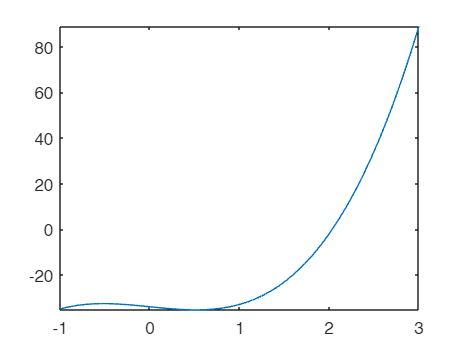


% Roots
%   Find roots given polynomial coeff in row vector
pfunc = @(x) 5*x.^3-4*x-34;
fplot(pfunc,[-1 3])

C = [5 0 -4 -34];
xr_roots = roots(C)

xr_roots =    2.0351 + 0.0000i
  -1.0175 + 1.5186i
  -1.0175 - 1.5186i


p = poly(xr_roots)

p =     1.0000    0.0000   -0.8000   -6.8000


pv = polyval(C,x0) % evaluate for coeffs C at x0

pv = -2


% fzero
%   *** This is the one that really is versatile, universal ***
xr_fz = fzero(func, x0)

xr_fz = 2.9994

xr_fzbr = fzero(func, [0 5])

xr_fzbr = 2.9994

## Ch7 - Optimization

help goldmin

  goldmin: minimization golden section search
  [x,fx,ea,iter]=goldmin(f,xl,xu,es,maxit,p1,p2,...):
  uses golden section search to find the minimum of f
  input:
    f = name of function
    xl, xu = lower and upper guesses
    es = desired relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by f
  output:
    x = location of minimum
    fx = minimum function value
    ea = approximate relative error (%)
    iter = number of iterations
  Can find max w/ g(x) = -f(x) -> max of f(x) = -g(x)



help fsolve

 fsolve solves systems of nonlinear equations of several variables.
 
    fsolve attempts to solve equations of the form:
              
    F(X) = 0    where F and X may be vectors or matrices.   
 
    fsolve implements three different algorithms: trust region dogleg,
    trust region, and Levenberg-Marquardt. Choose one via the option
    Algorithm: for instance, to choose trust region, set OPTIONS =
    optimoptions('fsolve','Algorithm','trust-region'), and then pass
    OPTIONS to fsolve.
     
    X = fsolve(FUN,X0) starts at the matrix X0 and tries to solve the 
    equations in FUN.  FUN accepts input X and returns a vector (matrix) of 
    equation values F evaluated at X. 
 
    X = fsolve(FUN,X0,OPTIONS) solves the equations with the default
    optimization parameters replaced by values in OPTIONS, an argument
    created with the OPTIMOPTIONS function.  See OPTIMOPTIONS fo

help fsearch

--- fsearch not found. Showing related topics. ---

graph.bfsearch                 - Breadth-first graph search
graph.dfsearch                 - Depth-first graph search

    Search the documentation for fsearch



## Ch8 - Linear Algebra

## Ch12 - Iterative Methods

help GaussSeidel

  GaussSeidel: Gauss Seidel method
  [x,ea,iter] = GaussSeidel(A,b,es,maxit): Gauss Seidel without relaxation
  input:
  A = coefficient matrix
  b = right hand side vector
  es = stop criterion (default = 0.00001%)
  maxit = max iterations (default = 50)
  output:
  x = solution vector
  ea = maximum relative error (%)
  iter = number of iterations



help GaussSeidelRelax

  GaussSeidel: Gauss Seidel method with relaxation
  [x,ea,iter] = GaussSeidelRelax(A,b,lambda,es,maxit): Gauss Seidel with relaxation
  input:
  A = coefficient matrix
  b = right hand side vector
  lambda = relation factor (default = 1)
  es = stop criterion (default = 0.00001%)
  maxit = max iterations (default = 50)
  output:
  x = solution vector
  ea = maximum relative error (%)
  iter = number of iterations



help newtmult 

  newtmult: Newton-Raphson root zeroes nonlinear systems
  [x,f,ea,iter]=newtmult(func,x0,es,maxit,p1,p2,...):
  uses the Newton-Raphson method to find the roots of
  a system of nonlinear equations
  input:
    func = name of function that returns f and J
    x0 = initial guess
    es = desired percent relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by function
  output:
    x = vector of roots
    f = vector of functions evaluated at roots (residual, ~ 0)
    ea = approximate percent relative error (%)
    iter = number of iterations



help jfreact2 

  jfreact2: Calculates the Jacobian matrix J and the function vector f
            for a system of two nonlinear equations, f1(x1, x2) and f2(x1, x2).
 
  NOTE: This specific implementation uses the finite-difference approximation
        for partial derivatives and assumes the system is defined by two
        external functions, u(x1, x2) and v(x1, x2), where f1=u and f2=v.
 
  input:
    x = current root estimate vector [x1; x2]
    varargin = optional parameters to pass to u and v functions (not used here)
 
  output:
    J = The 2x2 Jacobian matrix of partial derivatives
    f = The 2x1 function vector [f1; f2]
 
  -------------------------------------------------------------------------
  THE JACOBIAN MATRIX (J) STRUCTURE:
 
  J = [ df1/dx1, df1/dx2 ]   -> The first row is the gradient of f1
      [ df2/dx1, df2/dx2 ]   -> The second row is the gradient of f2
  -------------------------------------------------------------------------



help u % used in jfreact2 and newtmult

  u: fu = u(x1,x2)
    This is required for a poorly written newtmult code. 
    Have to pass in like this instead of as parameters.



help v % used in jfreact2 and newtmult

  v: fu = v(x1,x2)
    This is required for a poorly written newtmult code. 
    Have to pass in like this instead of as parameters.

